## Ejercicio 1

#### Inciso a

function [Q, R] = qr1(A)
    %
    %   Función que calcula la factorización QR de una matriz A
    %   utilizando el método de Gram-Schmidt inestable.
    %
    %   Inputs
    %       A: Matriz de tamaño mxn
    %
    %   Outputs
    %       Q: Matriz unitaria de tamaño mxn
    %       R: Matriz triangular superior de tamaño nxn
    %

    [m, n] = size(A);
    Q = zeros(m, n);
    R = zeros(n, n);

    for j = 1:n
        vj = A(:, j);
        for i = 1:j-1
            R(i, j) = Q(:, i)' * A(:, j);
            vj = vj - R(i, j) * Q(:, i);
        end
        R(j, j) = norm(vj);
        Q(:, j) = vj / R(j, j);
    end
end

#### Inciso b

function [Q, R] = qr2(A)
    %
    %   Función que calcula la factorización QR de una matriz A
    %   utilizando el método de Gram-Schmidt estable.
    %
    %   Inputs
    %       A: Matriz de tamaño mxn
    %
    %   Outputs
    %       Q: Matriz unitaria de tamaño mxn
    %       R: Matriz triangular superior de tamaño nxn
    %

    [m, n] = size(A);
    Q = zeros(m, n);
    R = zeros(n, n);
    V = A;

    for i = 1:n
        R(i, i) = norm(V(:, i));
        Q(:, i) = V(:, i) / R(i, i);
        for j = i+1:n
            R(i, j) = Q(:, i)' * V(:, j);
            V(:, j) = V(:, j) - R(i, j) * Q(:, i);
        end
    end
end

#### Inciso c

function [Q, R] = qr3(A)
    %
    %   Función que calcula la factorización QR de una matriz A
    %   utilizando la triangularización de Householder.
    %
    %   Inputs
    %       A: Matriz de tamaño mxn
    %
    %   Outputs
    %       Q: Matriz unitaria de tamaño mxm
    %       R: Matriz triangular superior de tamaño mxn
    %

    [m, n] = size(A);
    R = A;
    Q = eye(m);

    for j = 1:n
        x = R(j:m, j);
        e1 = zeros(length(x), 1);
        e1(1) = 1;
        vj = sign(x(1)) * norm(x) * e1 + x;
        vj = vj / norm(vj);
        R(j:m, j:n) = R(j:m, j:n) - 2 * vj * (vj' * R(j:m, j:n));
        Q(j:m, :) = Q(j:m, :) - 2 * vj * (vj' * Q(j:m, :));
    end

    Q = Q';
end

#### Inciso d

m = 20; 
A_random = rand(m);

[Q1, R1] = qr1(A_random);
[Q2, R2] = qr2(A_random);
[Q3, R3] = qr3(A_random);

error_random = zeros(3,2);

error_random(1,1) = norm(A_random - Q1 * R1, 2);
error_random(1,2) = norm(Q1 * Q1' - eye(m), 2);

error_random(2,1) = norm(A_random - Q2 * R2, 2);
error_random(2,2) = norm(Q2 * Q2' - eye(m), 2);

error_random(3,1) = norm(A_random - Q3 * R3, 2);
error_random(3,2) = norm(Q3 * Q3' - eye(m), 2);

format long
disp(error_random)

   1.0e-13 *

   0.007692526821796   0.465382760476284
   0.008479507867604   0.036110933100826
   0.022673395903316   0.013046334558406



#### Inciso e

A_hilbert = hilb(m);

[Q1, R1] = qr1(A_hilbert);
[Q2, R2] = qr2(A_hilbert);
[Q3, R3] = qr3(A_hilbert);

error_hilbert = zeros(4,2);

error_hilbert(1,1)  = norm(A_hilbert - Q1 * R1, 2);
error_hilbert(1,2) = norm(Q1 * Q1' - eye(m), 2);

error_hilbert(1,2) = norm(A_hilbert - Q2 * R2, 2);
error_hilbert(2,2)  = norm(Q2 * Q2' - eye(m), 2);

error_hilbert(3,1) = norm(A_hilbert - Q3 * R3, 2);
error_hilbert(3,2) = norm(Q3 * Q3' - eye(m), 2);

% Comparación con la factorización QR de MATLAB
[Q4, R4] = qr(A_hilbert);

error_hilbert(4,1) = norm(A_hilbert - Q4 * R4, 2);
error_hilbert(4,2) = norm(Q4 * Q4' - eye(m), 2);

format long
disp(error_hilbert)

   0.000000000000000   0.000000000000000
                   0   0.998956338417536
   0.000000000000000   0.000000000000001
   0.000000000000000   0.000000000000001



## Ejercicio 2

#### Inciso a

m = 12;
x = ones(m, 1); % solución exacta
A = hilb(m);
b = A * x;

fprintf("El número de condición es %d", cond(A))

El número de condición es 16223826740810282

#### Inciso b

[L, U, P] = lu(A);
y = L \ (P * b);
x_LU = U \ y;

error_LU = norm(x - x_LU, 2);

fprintf("El error por LU es %d", error_LU)

El error por LU es 5.756644e-01

#### Inciso c 

[Q, R] = qr(A);
x_QR = R \ (Q' * b);

error_QR = norm(x - x_QR, 2);

fprintf("El error por QR es %d", error_QR)

El error por QR es 7.587727e-01

#### Inciso d

L = chol(A, 'lower');
y = L \ b;
x_Chol = L' \ y;

error_Chol = norm(x - x_Chol, 2);

fprintf("El error por Cholesky es %d", error_Chol)

El error por Cholesky es 6.777753e-01

#### Inciso e

[U, S, V] = svd(A);
x_SVD = V * (S \ (U' * b));


error_SVD = norm(x - x_SVD, 2);

fprintf("El error por SVD es %d", error_SVD)

El error por SVD es 1.379475e+00

#### Inciso g

rango = 9;
A_nu_inv = V(:, 1:rango) * inv(S(1:rango, 1:rango)) * U(:, 1:rango)';
x_aprox = A_nu_inv * b;

error_approx = norm(x - x_aprox, 2);

fprintf("El error por rango 9 es %d", error_approx)

El error por rango 9 es 6.547244e-06

## Ejercicio 3

Inciso a

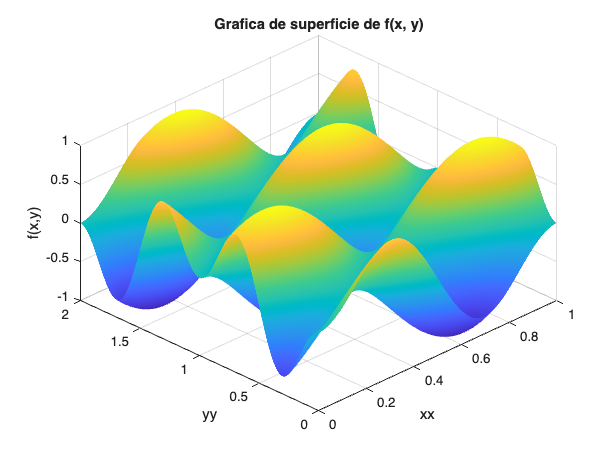

x = linspace(0,1,100);
y = linspace(0,2,200);

[xx,yy] = meshgrid(x,y);

f = @(x,y) sin(2.*pi.*(x+y)).*sin(pi.*(x-y));

figure;
surf(xx,yy,f(xx,yy))
view([-45 45])
shading interp
xlabel('xx')
ylabel('yy')
zlabel('f(x,y)')
title('Grafica de superficie de f(x, y)')

Inciso b

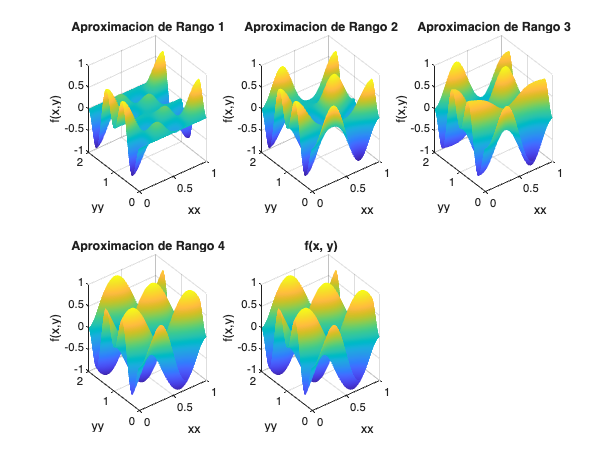

zz = f(xx,yy);
[U,S,V] = svd(zz);
val = diag(S);
aprox = cell(4,1);
aprox{1} = val(1)*U(:,1)*V(:,1)';
for i = 2:4
    aprox{i} = aprox{i-1} + val(i)*U(:,i)*V(:,i)';
end

figure;
for i = 1:4
    subplot(2,3,i);
    surf(xx, yy, aprox{i})
    shading interp
    xlabel('xx')
    ylabel('yy')
    zlabel('f(x,y)')
    title(sprintf('Aproximacion de Rango %d', i))
end

subplot(2,3,5)
surf(xx,yy,f(xx,yy))
shading interp
xlabel('xx')
ylabel('yy')
zlabel('f(x,y)')
title('f(x, y)')

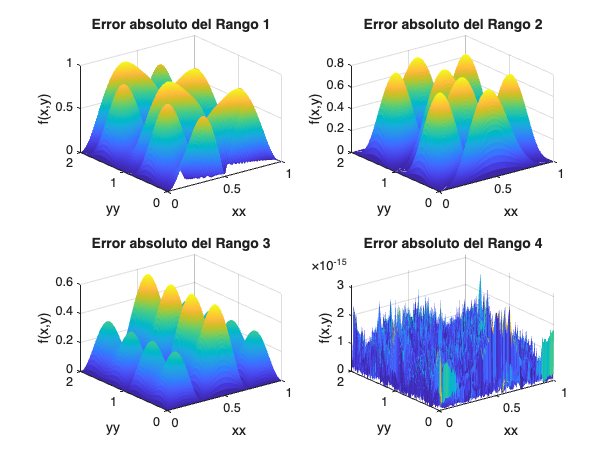


figure;
error = cell(4,1);
for i = 1:4
    error{i} = abs(f(xx, yy) - aprox{i});
    subplot(2, 2, i)
    surf(xx, yy, error{i})
    shading flat
    xlabel('xx')
    ylabel('yy')
    zlabel('f(x,y)')
    title(sprintf('Error absoluto del Rango %d', i))
end

Inciso c

disp(val(1:4))

  35.791933448753504
  35.440972052131968
  35.090062695868767
  35.090062695868767



rank(zz)

ans =      4


Inciso d

disp(norm(cos(2.*pi.*x).*cos(pi.*x)) * norm(sin(2.*pi.*y).*sin(pi.*y)))

  35.791933448753504



disp(norm(sin(2.*pi.*x).*sin(pi.*x)) * norm(cos(2.*pi.*y).*cos(pi.*y)))

  35.440972052131976



disp(norm(sin(2.*pi.*x).*cos(pi.*x)) * norm(cos(2.*pi.*y).*sin(pi.*y)))

  35.090062695868752



disp(norm(cos(2.*pi.*x).*sin(pi.*x)) * norm(sin(2.*pi.*y).*cos(pi.*y)))

  35.090062695868752



## Ejercicio 4

Inciso b

function c = calculo_aprox(f, n)
    %
    %   Hace un cálculo aproximado de la función aproximada con 
    %   la matriz de Hilbert
    %
    %   Inputs
    %       f: función a aproximar 
    %       n: tamaño del polinomio interpolador
    %
    %   Outputs
    %       c: vector de constantes de la factorización Mc = b

    M = zeros(n);
    b = zeros(n,1);
    for i = 1:n
        b(i) = integral(@(x) f(x).*x.^(i-1), 0, 1);
        for j = 1:n
            M(i,j) = 1/(i+j-1);
        end
    end
    c = M\b;
end

f = @(x) cos(4.*pi.*x);
c = calculo_aprox(f, 10);
p = @(x) polyval(c(end:-1:1), x);
integral(@(x) (f(x) - p(x)).^2, 0, 1)

ans =      1.733766301763702e-04


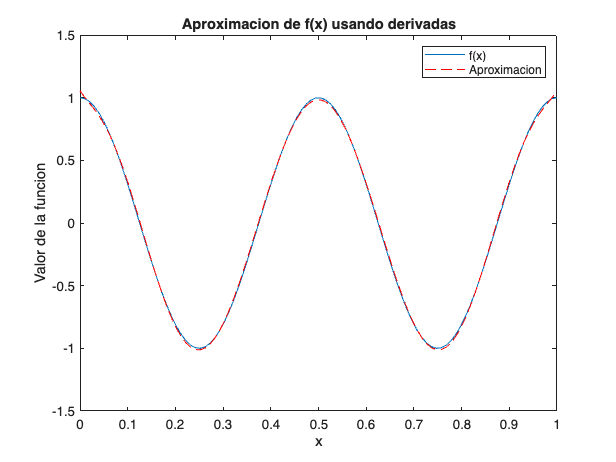

xx = linspace(0,1); 
figure;
plot(xx, f(xx), '-', 'DisplayName', 'f(x)')
hold on
plot(xx, p(xx), 'r--', 'DisplayName', 'Aproximacion')
hold off
legend;
title('Aproximacion de f(x) usando derivadas');
xlabel('x');
ylabel('Valor de la funcion');

Inciso c

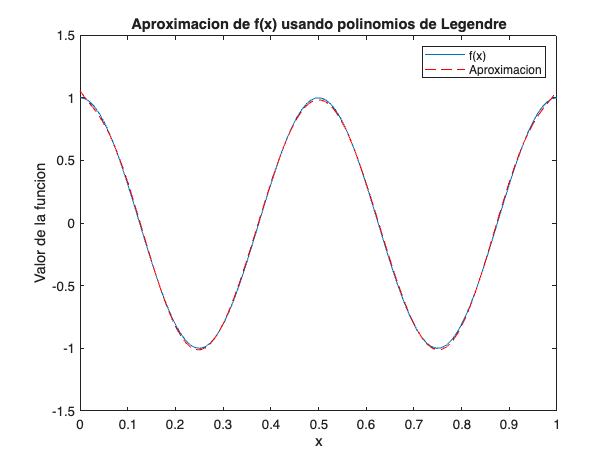

function p = aprox_leg(n, f)
    %
    %   Hace un cálculo aproximado de la función aproximada con 
    %   los polinomios de legendre
    %
    %   Inputs
    %       f: función a aproximar 
    %       n: tamaño del polinomio interpolador
    %
    %   Outputs
    %       p: polinomio interpolador 

    pn = cell(n, 1);
    pn{1} = @(x) 1; 
    pn{2} = @(x) x; 
    
    % Construye los polinomios de Legendre
    for k = 2:(n-1)
        pn{k+1} = @(x) ((2*k-1)*x.*pn{k}(x) - (k-1)*pn{k-1}(x)) / (k);
    end
    
    % Calcula los betas
    betas = zeros(n, 1);
    for k = 1:n
        betas(k) = integral(@(x) f(x) .* pn{k}(2*x-1), 0, 1) / ...
                   integral(@(x) pn{k}(2*x-1).^2, 0, 1, 'ArrayValued', true);
    end

    % suma para obtener el polinomio
    p = @(x) sum(cell2mat(arrayfun(@(k) betas(k) .* pn{k}(2*x-1), ...
        1:n, 'UniformOutput', false)));
end

n = 10;
p = aprox_leg(n, f);

figure;
xx = linspace(0, 1, 100); 
plot(xx, f(xx), '-', 'DisplayName', 'f(x)'); 
hold on;
plot(xx, arrayfun(p, xx), 'r--', 'DisplayName', 'Aproximacion');
hold off;
legend;
title('Aproximacion de f(x) usando polinomios de Legendre');
xlabel('x');
ylabel('Valor de la funcion');


norma_error = integral(@(x) (f(x) - arrayfun(p, x)).^2, 0, 1);
disp(['Norma del error: ', num2str(norma_error)]);

Norma del error: 0.00017338


## Ejercicio 7

#### Inciso a

data = load("data/data.mat");

#### Inciso b

function fxc = funcion(x, c)
    % 
    %   Función que evalúa 
    %   f(x, c) = c1 * exp(-c2 * x) * sin(c3 * x + c4)
    %
    %   Inputs
    %       x: vector con las x
    %       c: vector con los coeficientes [c1, c2, c3, c4]
    %
    %   Output
    %       f: valores de f(x, c) evaluados en x
    
    fxc = c(1) * exp(-c(2) * x) .* sin(c(3) * x + c(4));
end

function Jf = jacobiano_f(x, c)
    %
    %   Función que calcula el Jacobiano de f respecto a los
    %   coeficientes c = [c1, c2, c3, c4].
    %
    %   Inputs
    %       x: vector con las x
    %       c: vector con los coeficientes [c1, c2, c3, c4]
    %
    %   Output
    %       J: matriz Jacobiana evaluada en x y c
    
    Jf = zeros(length(x), 4);

    Jf(:, 1) = exp(-c(2) * x) .* sin(c(3) * x + c(4));        
    Jf(:, 2) = -c(1) * x .* exp(-c(2) * x) .* sin(c(3) * x + c(4));    
    Jf(:, 3) = c(1) * exp(-c(2) * x) .* x .* cos(c(3) * x + c(4));
    Jf(:, 4) = c(1) * exp(-c(2) * x) .* cos(c(3) * x + c(4));    
end

function [c, iter, norma_delta_c, num_cond] = minimos_cuadrados(x, y, c0)
    %
    %   Función que ejecuta el algoritmo para minimizar la diferencia
    %   entre la función f(x, c) y los valores observados y.
    %
    %   Inputs
    %       x: vector con las x
    %       y: vector con las y
    %       c0: vector con los coeficientes [c1, c2, c3, c4]
    %
    %   Outputs
    %       c: vector de coeficientes ajustados
    %       iter: número de iteraciones requeridas
    %       norma_delta_c: valor de la norma de delta c por iteración
    %       num_cond: número de condición por itereción
    
    
    tol = 1e-8;
    c = c0;
    iter = 0;
    delta_c = inf;
    num_cond = [];
    
    while norm(delta_c, inf) > tol
       
        dif = y - funcion(x, c);
        J = jacobiano_f(x, c);
        
        delta_c = (J' * J) \ (J' * dif);
        c = c + delta_c;

        iter = iter + 1; 
        norma_delta_c(iter) = norm(delta_c, inf);
        num_cond(iter) = cond(J);
    end
end

#### Inciso c

x = data.x;
y = data.y;
c0 = [1.1; 0.4; 2.1; 0.2];

% Ejecución del algoritmo
[c, iter, norma_delta_c, num_cond] = minimos_cuadrados(x, y, c0);

disp("Número de iteraciones:");

Número de iteraciones:


disp(iter);

     7



disp("Coeficientes ajustados:");

Coeficientes ajustados:


disp(c);

   0.996624262952883
   0.497520108541692
   1.998430950161934
   0.001284297892960



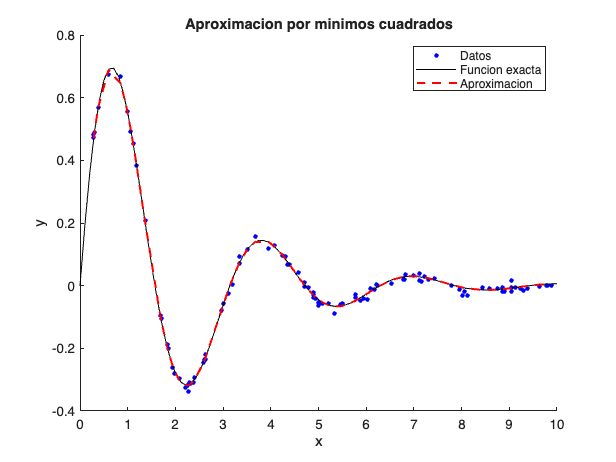


% Función exacta
c_exact = [1; 0.5; 2; 0];
xx = linspace(0, 10);
yy = funcion(xx, c_exact);

% Gráficas
figure;
hold on;
plot(x, y, 'b.', 'DisplayName', 'Datos', 'MarkerSize', 10);
plot(xx, yy, 'k-', 'DisplayName', 'Funcion exacta');
plot(sort(x), funcion(sort(x), c), 'r--', 'DisplayName', 'Aproximacion', 'LineWidth', 1.5);
legend;
xlabel('x');
ylabel('y');
title('Aproximacion por minimos cuadrados');
hold off;

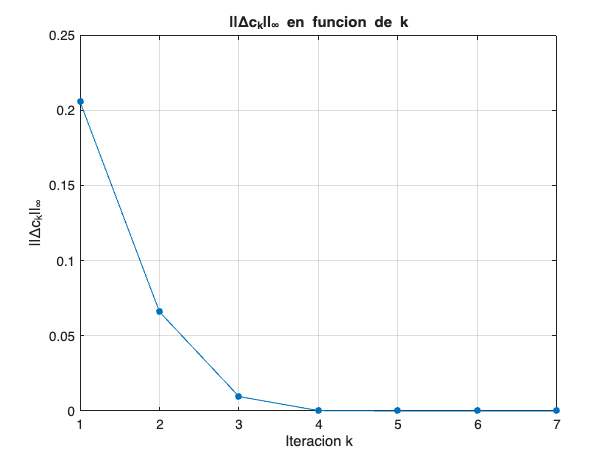


figure;
plot(1:iter, norma_delta_c, '.-', 'MarkerSize', 15);
xlabel('Iteracion k');
ylabel('||\Deltac_k||_\infty');
title('||\Deltac_k||_\infty en funcion de k');
grid on;

#### Inciso d

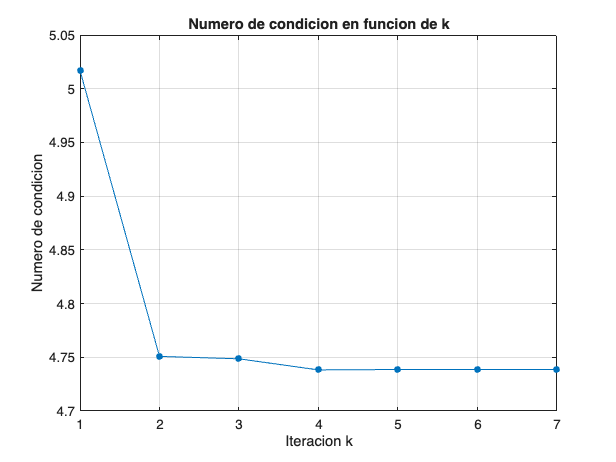

figure;
plot(1:iter, num_cond, '.-', 'MarkerSize', 15);
xlabel('Iteracion k');
ylabel('Numero de condicion');
title('Numero de condicion en funcion de k');
grid on;

#### Inciso e

c0 = [1; 1; 1; 1];
[c, iter] = minimos_cuadrados(x, y, c0);


disp("Número de iteraciones:");

Número de iteraciones:


disp(iter);

     9



disp("Coeficientes ajustados:");

Coeficientes ajustados:


disp(c);

   NaN
   NaN
   NaN
   NaN



## Ejercicio 8

Inciso b

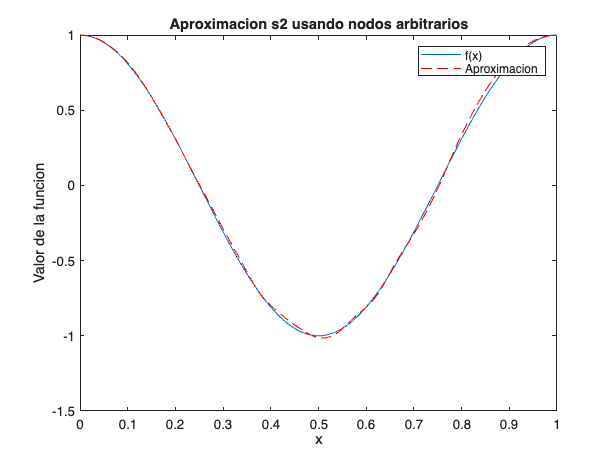

function sigmas = calculo_s2(xn, yn)
    %
    %   Calcula los sigmas para poder realizar s2
    %
    %   Inputs
    %       xn: coordenadas x de los puntos a interpolar
    %       yn: coordenadas y de los puntos a interpolar
    %
    %   Outputs
    %       sigmas: coeficientes de la función s2 

    m = length(xn);
    x = zeros(m);
    y = zeros(m,1);
    for i = 1:(m-1)
        % diferencias de xn
        x(i,i) = (xn(i+1)-xn(i))/2;
        x(i,i+1) = x(i,i);
        % diferencias de yn
        y(i) = yn(i+1) - yn(i);
    end
    % condición de sigmas, que el último debe de ser igual al primero
    x(end, 1) = 1;
    x(end, end) = -1;
    y(end) = 0;

    sigmas = x\y;
end

m = 15;
xn = sort(rand(m+1,1));
f = @(x) cos(2.*pi.*x);
xn(1) = 0;
xn(end) = 1;
yn = f(xn);
sigmas = calculo_s2(xn, yn);

function s2 = s2(sigmas, x, xn, yn)
    %
    %   Calcula la función s2 en un punto x
    %
    %   Inputs 
    %       sigmas: calculados con calculo_s2
    %       x: punto a evaluar
    %       xn: coordenadas x de los puntos
    %       yn: coordenadas y de los puntos
    %
    %   Outputs
    %       s2: valor de s2 en x 

    % busca en qué intervalo está
    nodes = find(xn>x);
    if x == 1 
        lower = length(xn)-1;
    else 
        lower = nodes(1)-1;
    end
    
    % y procede a hacer la función
    s1 = sigmas(lower);
    s2 = sigmas(lower+1);
    y1 = yn(lower);
    x1 = xn(lower);
    x2 = xn(lower + 1);
    s2 = y1 + s1.*(x - x1) + ((s2 - s1)/(2 * (x2 - x1)))*(x-x1)^2;
end
figure;
xx = linspace(0,1);
yy = arrayfun(@(x) s2(sigmas, x, xn, yn), xx);
plot(xx, f(xx),'', 'DisplayName', 'f(x)')
hold on;
plot(xx, yy, 'r--', 'DisplayName', 'Aproximacion')
hold off;
legend;
title('Aproximacion s2 usando nodos arbitrarios');
xlabel('x');
ylabel('Valor de la funcion');


figure;
plot(xx, abs(f(xx) - yy))
disp(max(abs(f(xx) - yy)))

   0.042074311374704



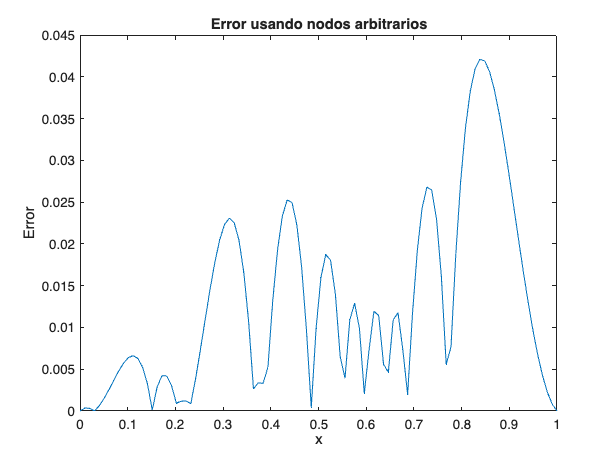

title('Error usando nodos arbitrarios');
xlabel('x');
ylabel('Error');

Inciso c

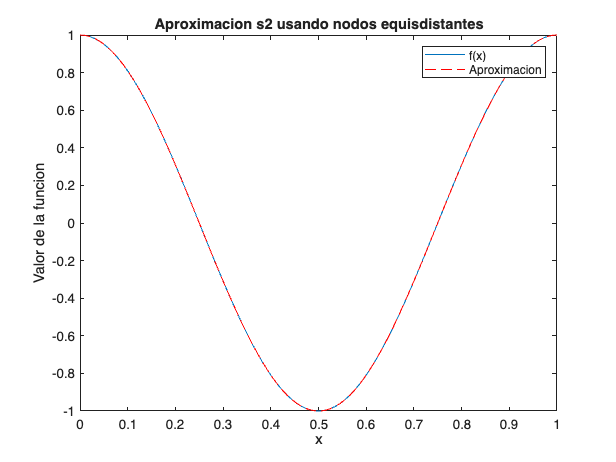

xn = linspace(0,1,m+1);
yn = f(xn);
sigmas = calculo_s2(xn, yn);
yy = arrayfun(@(x) s2(sigmas, x, xn, yn), xx);
figure;
plot(xx, f(xx),'', 'DisplayName', 'f(x)')
hold on;
plot(xx, yy, 'r--', 'DisplayName', 'Aproximacion')
hold off;
legend;
title('Aproximacion s2 usando nodos equisdistantes');
xlabel('x');
ylabel('Valor de la funcion');


figure;
plot(xx, abs(f(xx) - yy))
disp(max(abs(f(xx) - yy)))

     6.098027184256172e-04



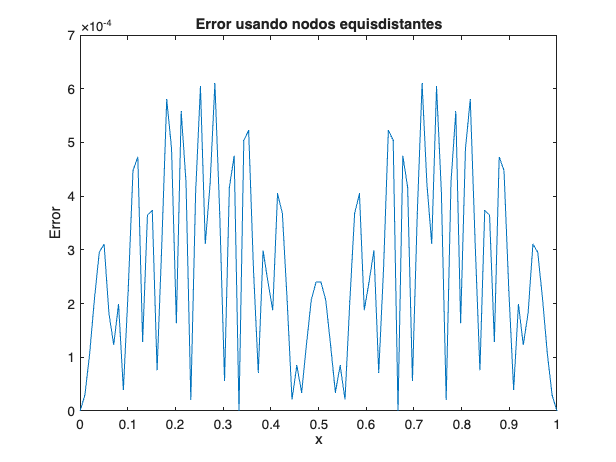

title('Error usando nodos equisdistantes');
xlabel('x');
ylabel('Error');

Inciso d

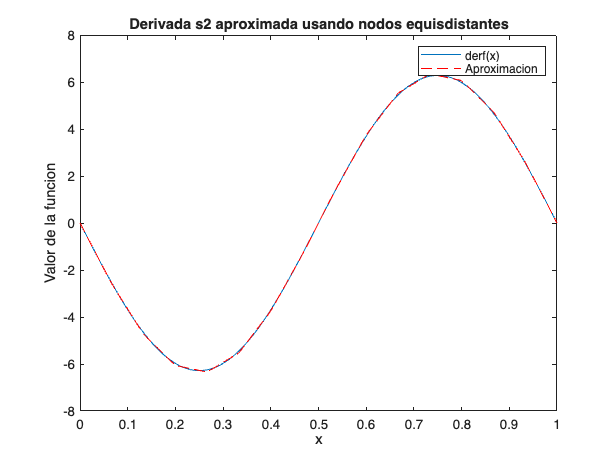

function s2 = der_s2(sigmas, x, xn)
    %
    %   Función de la derivada explícita de s2
    %
    %   Inputs 
    %       sigmas: calculados con calculo_s2
    %       x: punto a evaluar
    %       xn: coordenadas x de los puntos
    %
    %   Outputs
    %       s2: valor de s2 en x 

    % Mismo principio de búsqueda
    nodes = find(xn>x);
    if x == 1 
        lower = length(xn)-1;
    else 
        lower = nodes(1)-1;
    end
    
    % Pero diferente fórmula, no ocupamos yn
    s1 = sigmas(lower);
    s2 = sigmas(lower+1);
    x1 = xn(lower);
    x2 = xn(lower + 1);
    s2 = s1 + ((s2 - s1)/((x2 - x1)))*(x-x1);
end

derf = @(x) -2.*pi.*sin(2.*pi.*x);
yy = arrayfun(@(x) der_s2(sigmas, x, xn), xx);
figure;
plot(xx, derf(xx),'', 'DisplayName', 'derf(x)')
hold on;
plot(xx, yy, 'r--', 'DisplayName', 'Aproximacion')
hold off;
legend;
title('Derivada s2 aproximada usando nodos equisdistantes');
xlabel('x');
ylabel('Valor de la funcion');


figure;
plot(xx, abs(derf(xx) - yy))
disp(max(abs(derf(xx) - yy)))

   0.080983371716743



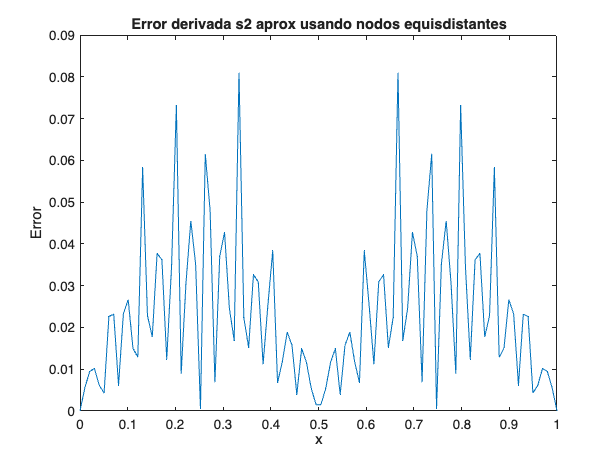

title('Error derivada s2 aprox usando nodos equisdistantes');
xlabel('x');
ylabel('Error');